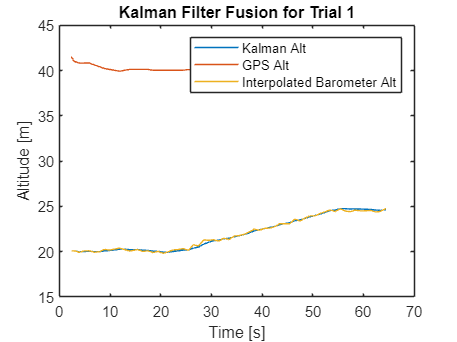

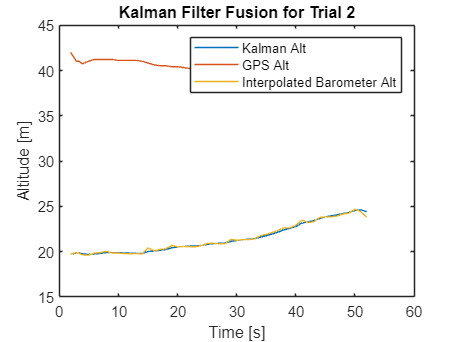

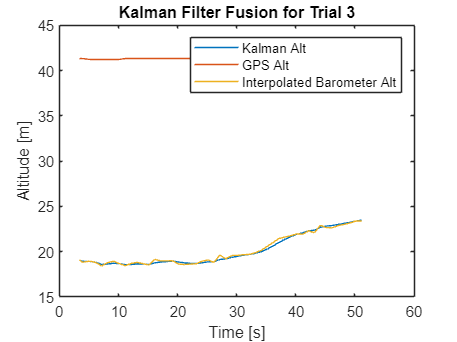

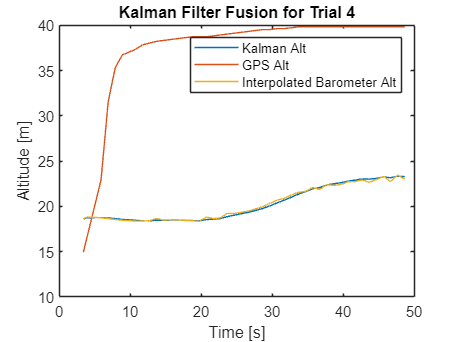

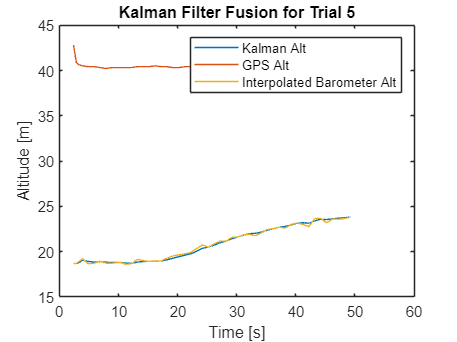

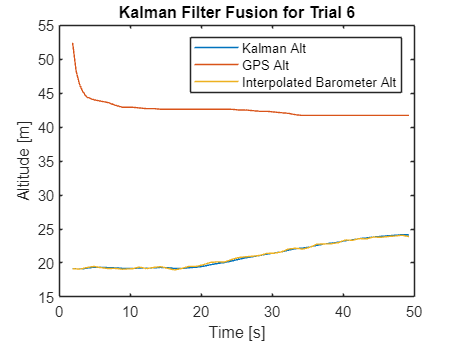

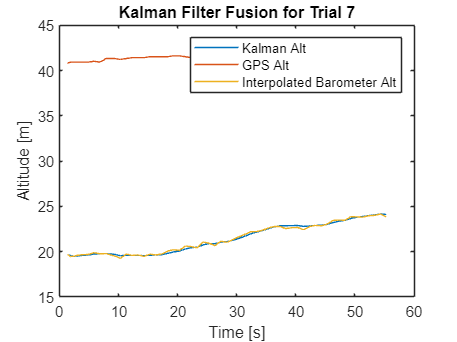

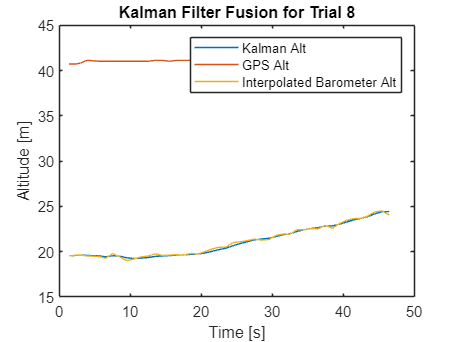

deltaAlt=[];
endAlt=[];
groundTruthChange=4.6482;
groundTruthABS=51+4.6482;%From google map and measurment
for i=1:length(fileList)
    filename=string(fileList(i));
    [kalmanAlt,gpsAlt,barAlt,time]=getKalman(filename);
    nonNaNIndices = find(~isnan(kalmanAlt));
    if length(nonNaNIndices)>2
        endAlt=[endAlt,kalmanAlt(nonNaNIndices(end))];
        deltaAlt=[deltaAlt,kalmanAlt(nonNaNIndices(end))-kalmanAlt(nonNaNIndices(1))];
        figure(i)
        plot(time,kalmanAlt)
        hold on
        plot(time,gpsAlt)
        plot(time,barAlt)
        ylabel("Altitude [m]")
        xlabel("Time [s]")
        title("Kalman Filter Fusion for Trial "+num2str(i))
        legend("Kalman Alt","GPS Alt","Interpolated Barometer Alt")
        hold off
    end

end

changeError=deltaAlt-groundTruthChange;
muChangeEr=mean(changeError)

muChangeEr = 0.0514

sigChangeEr=std(changeError)

sigChangeEr = 0.3106

absEr=endAlt-groundTruthABS;
muABSEr=mean(absEr)

muABSEr = -34.3950

sigABSEr=std(absEr)

sigABSEr = 2.1383